# Classification Part II - Support Vector Machines

*Shira Lupkin - 2020, Bart Krekelberg - March 2025*

## Support Vector Machines - Theory

### Hyperplanes

Support Vector Machines are a type of s*upervised * learning algorithm used to classify data into two classes by finding a "hyperplane" that separates one class of data from another. Because of its role in partitioning the data, this type of hyperplane is referred to as a separating hyperplane.  Looking at the general equation for a hyperplane ($\beta_0 +\beta_1 X_1 +\beta_2 X_2 +\;\ldotp \ldotp \ldotp \beta_p X_p =0$) we can see that it is a just a linear function. So, if we are dealing with 2-features (*p *= 2), the hyperplane is a line; if  *p *= 3, the hyperplane is a plane, and so on.  The vector of beta-weights for this linear function, $\beta =\left(\beta_1 ,\beta_2 ,\ldotp \ldotp \ldotp ,\beta_p \right)\;,\;$is called the normal vector and is orthogonal to the surface of the hyperplane. Let's look at this graphically to see why this is important. For simplicity, we are going to focus on a scenario with 2-dimensions (i.e. each observation or data point is defined by two numbers). 

### 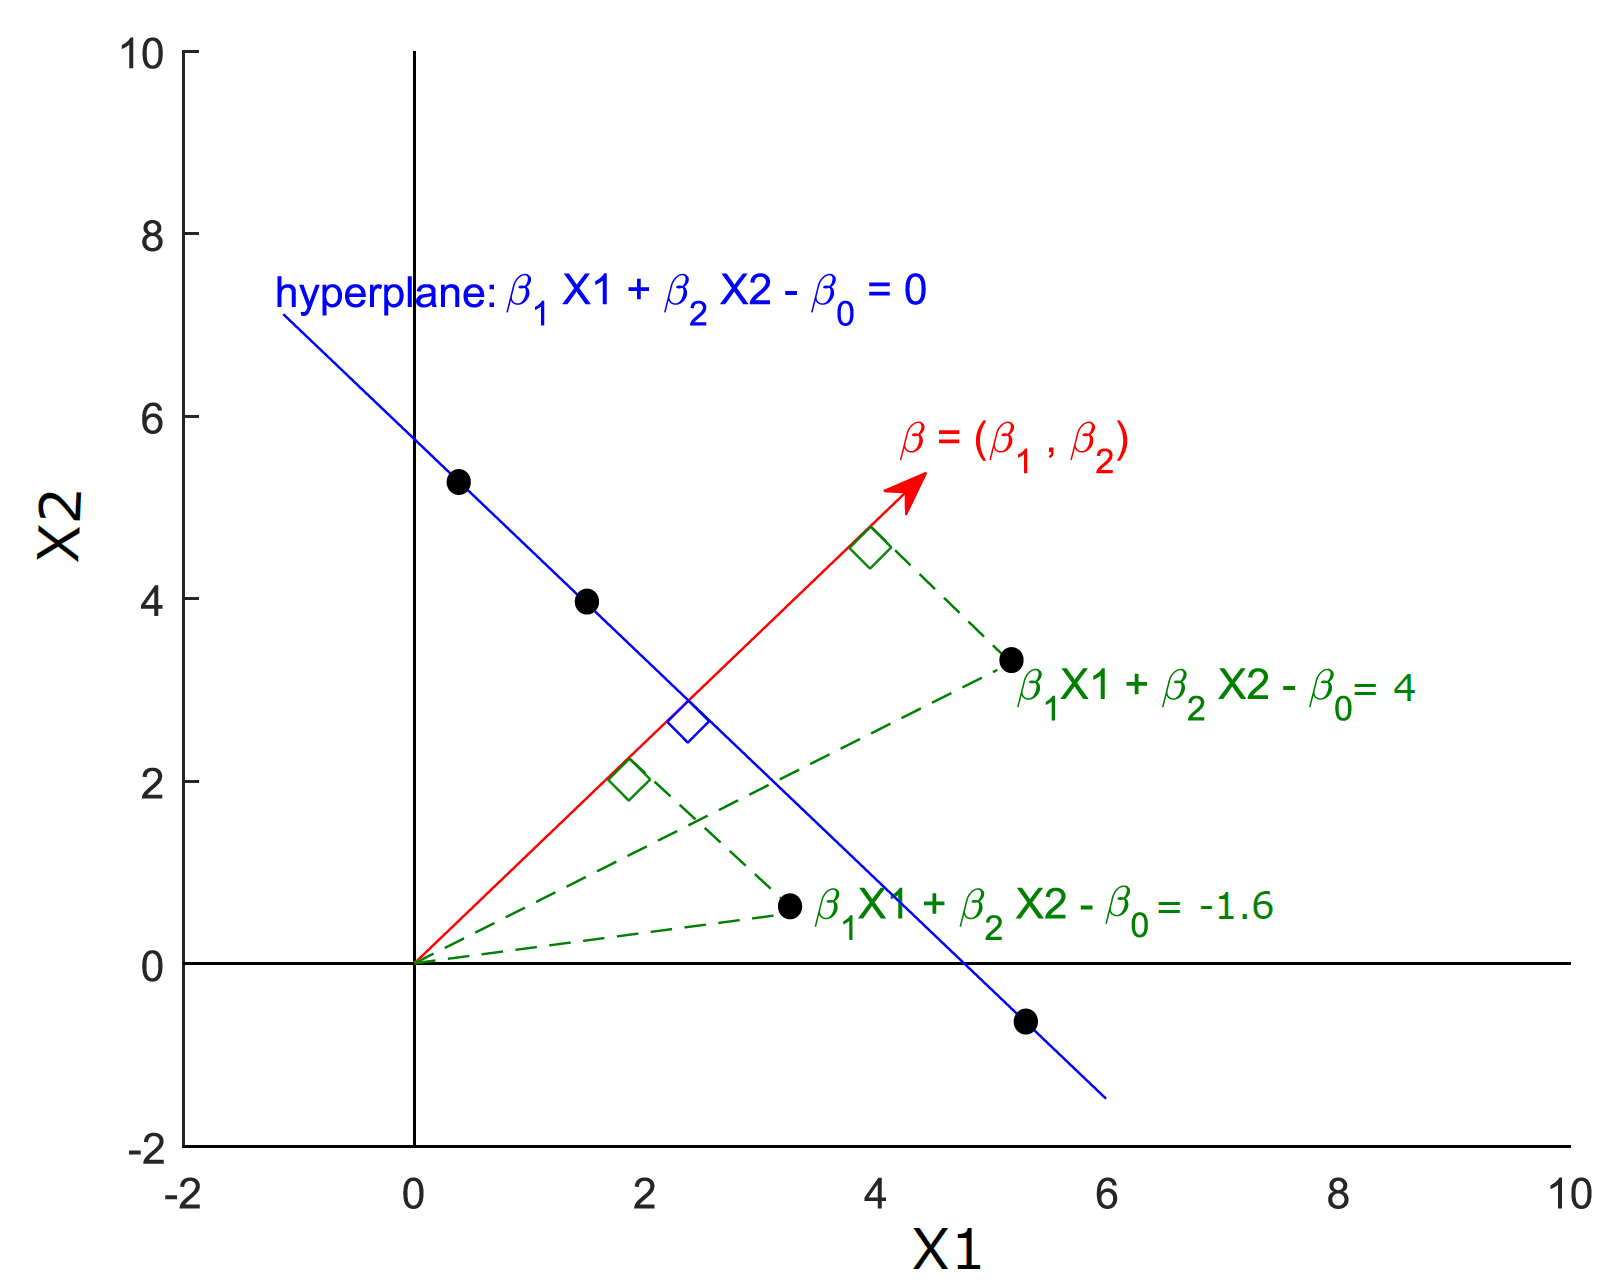

[modeled off of an image in this video](https://www.youtube.com/watch?v=m59UOo5jAFU&list=PLAOUn-KLSAVOf4Uk-WbLGPUDFjMSyytkw&index=1&t=20s)

In this figure,  blue line represents the hyperplane, the red arrow is the normal vector, and the black dots are data points. When dealing with support vector machines, the normal vector is constrained so that it is a unit vector (by making sure the sum of squares of the betas is equal to 1). This is important because since it is both orthogonal to the hyperplane *and *a unit vector, when we evaluate the linear function for any of the data points, the value represents the distance between that point and the hyperplane. This is called the projection of the data point onto the normal vector. Any point that is to the right of the hyperplane (blue line) will have a positive value, values to the left of the hyperplane will have negative values, and points *on* the hyperplane are equal to 0. The importance of these signed distances will become clear in the next section. 

### Fully separable data: Maximal Margin Classifier

Let's say that we have collected data from a touch screen and we are interested in classifying these movements into "right movements" and "left movements" based on the position of the hand on along the x-axis of the screen.

clear;clc
load ../data/tutorial1
clf
gscatter(data(:,1),data(:,2),labels); 
hold on
title('Hand Movements')
xlabel('horizontal position')
pbaspect([3 1 1])
legend('right','left')
yticklabels({});

The first thing to notice about this data is that there is no overlap between the two sets of points. As a result, it would be simple to find a point that separated these two points (i.e., a 0-dimensional hyperplane). Using this hyperplane we could then easily classify new data into one of the two classes based off of whch side of the hyperplane it falls on. But, in this case there are multiple lines that could be drawn all of which could cleanly separate the data.  This is where the signed distances we discussed in the previous section come into play. The hyperplane that would do the best job at accurately classifying any new data points is halfway between the points, in each class, that are closest to the hyperplane (circled in black).  The distance between the aforementioned points is called the *margin *(gray patch)*. *Using the midpoint of the margin creates the wides possible margin that would allow us to accurately classify new data. This type of classification is, therefore, called *maximal margin classification*. 

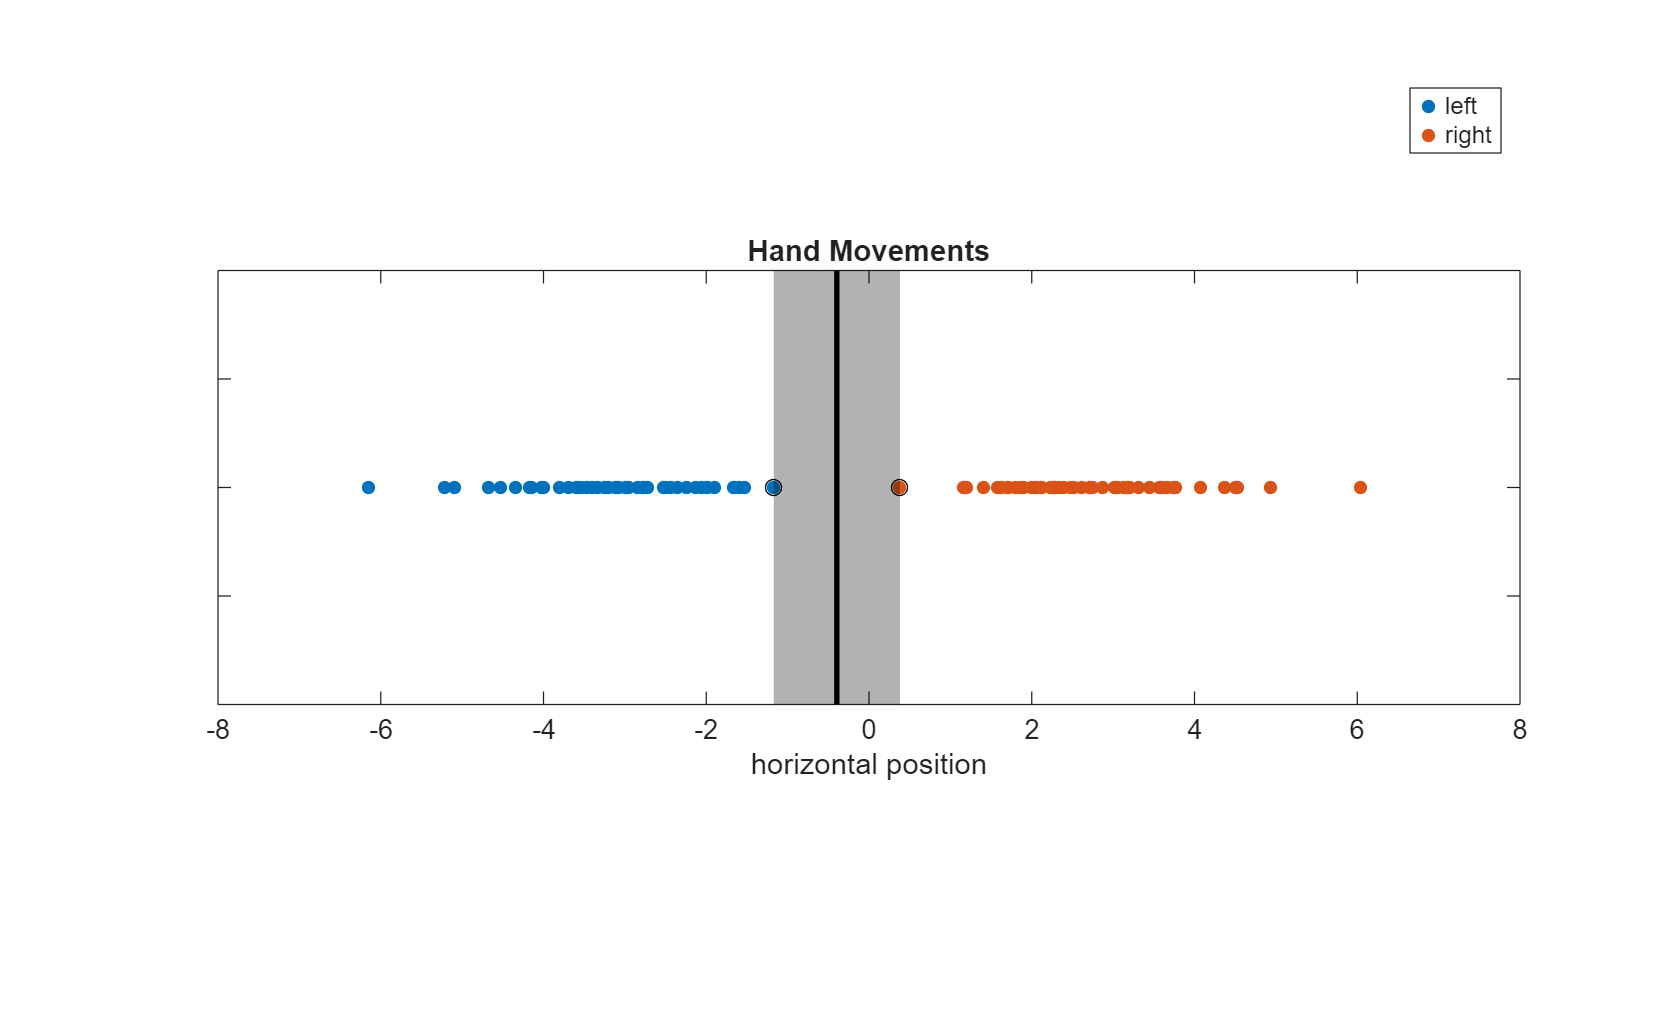

% find the index and values of the two closest points
maxR = max(data(labels==0,1));
maxIdx = find(data(:,1) == maxR);
minL = min(data(labels==1,1));
minIdx = find(data(:,1) == minL);

% replot the data and circle the closest points
plot(data(maxIdx,1),data(maxIdx,2),'ko')
plot(data(minIdx,1),data(minIdx,2),'ko')

% calculate the midpoint between distance between them
distance = (minL-maxR)/2;
ylims = get(gca,'Ylim');
patch([maxR maxR minL minL],[ylims(1) ylims(2) ylims(2) ylims(1)],'k','EdgeColor','none','FaceAlpha',0.3)
line([maxR+distance maxR+distance],[ylims],'color','k','LineWidth',2)
legend('left','right')

In this example, we classified the data using a single feature. But, this type of classification can be used just as easily with more features. Note that while I have a drawn a line to indicate the placement of the hyperplane, in 1-dimension the hyperplane is just a single point on the axis, not a line. This is true for the example in the next section as well. 

### Non-separable data: Soft-Margin Classifiers

The problem, however, with maximal margin classifiers is that they only work if the data from the two classes are completely separable. If there are outliers that are on the "wrong" side of the hyperplane, we can no longer find the maximal margin. More often than not, data are *not *completely separable so we need a classifier with a so-called soft-margin that will not be affected by a small number of outliers on the wrong sides of the margin and allow for some misclassifications. These classifiers are aptly named, *soft-margin classifiers*. But they go by another name as well, *support-vector classifiers *(SVC). 

clear;clc
load ../data/tutorial2
figure
clf
gscatter(data(:,1),data(:,2),labels); hold on
pbaspect([3 1 1])
yticklabels({})
title('Hand Movements')
xlabel('horizontal position')

The goal with an SVC is to find the "sweet-spot" where there are few misclassifications but where the margin is still sufficiently wide to allow for the majority of observations to be correctly classified. The name, support-vector classifier, comes from the name of the points that fall within or on the soft-margin. These points are called support-vectors. In the graph below, the support vectors are the nlue and red points that are on the wrong side of the hyperplane as well as the red-point that is on the correct side of of the hyperplane, but within the margin. 

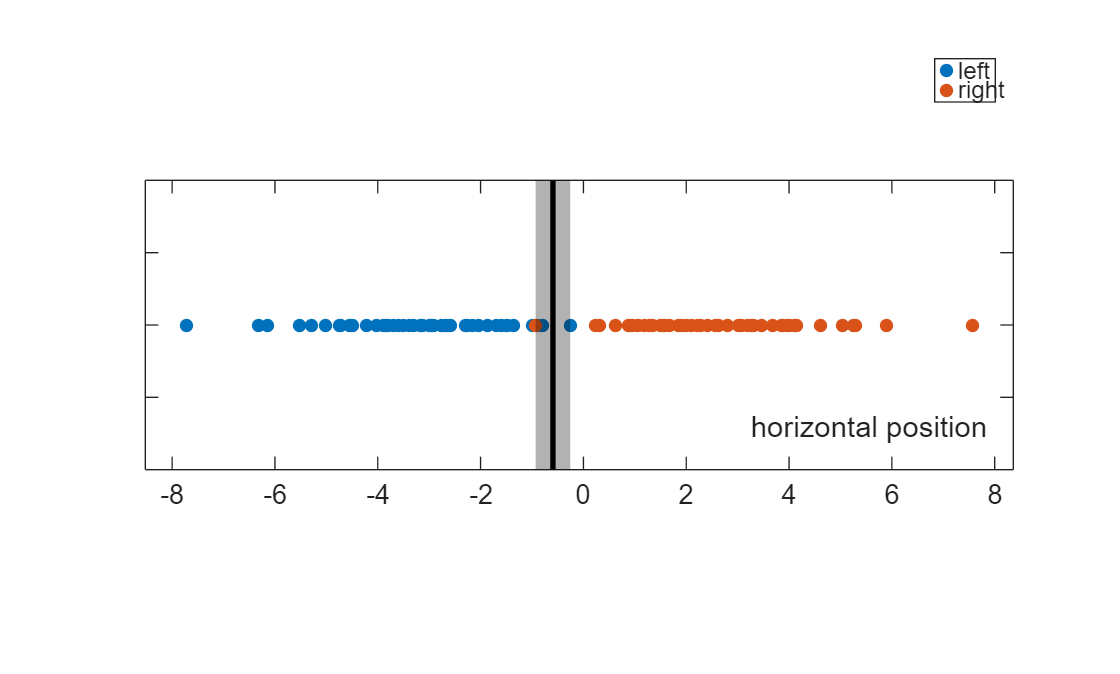

% find the index and values of the two closest points
maxR = max(data(labels==0,1));
maxIdx = find(data(:,1) == maxR);
minL = min(data(labels==1,1));
minIdx = find(data(:,1) == minL);


% calculate the midpoint between distance between them
distance = (minL-maxR)/2;

ylims = get(gca,'Ylim');

patch([maxR maxR minL minL],[ylims(1) ylims(2) ylims(2) ylims(1)],'k','EdgeColor','none','FaceAlpha',0.3)

line([maxR+distance maxR+distance],[ylims],'color','k','LineWidth',2)
legend('left','right')

The support vectors define the orientation of the hyperplane and the more support vectors you have, the more stable that hyperplane is (i.e., it will not really change if we added more points to the data set). However, this becomes a trade-off between stability and generalizability. The fewer points, the more generalizable, but the less stable the separating hyperplane is.  The number of support vectors is a parameter that can be manually tuned using the `'BoxConstraint'` argument within `fitcsvm`. However, for the examples in this document, we are going to let Matlab decide the number for us. For more information about how this is done, look through the Matlab documentation for `fitcsvm`.

### SVC vs. SVM: Kernels

Up to this point, we have discussed separating things with a hyperplane defined by a linear function. As you can imagine, not all data is separable using a linear boundary.  By using a well-chosen "kernel"  the classifier can draw any curve in the high dimensional space to separate classes. The two most common kernels are the polynomial kernel and the radial kernel. Support Vector Machines (SVMs) are, put simply, SVCs that use a kernel function to create the classification boundary. In fact, the reason we typically only speak about SVMs and not SVCs is because they are the more generalizable case--an SVC can be thought of as an SVM with a linear kernel. 

We are going to stick to linear SVMs for the remainder of this unit. However, if you would like more information about how and when to use kernels here are some helpful videos on the intuition behind the [polynomial kernel](https://www.youtube.com/watch?v=Toet3EiSFcM&list=PLzwVRKnDdXIfAOzylenX_4HIwT1fHWPp8&index=2), and the [radial (rbf) kernel](https://www.youtube.com/watch?v=Qc5IyLW_hns&list=PLzwVRKnDdXIfAOzylenX_4HIwT1fHWPp8&index=3), as well as [this video](https://www.youtube.com/watch?v=ooYwHNvH-YU&list=PLAOUn-KLSAVOf4Uk-WbLGPUDFjMSyytkw&index=3) which contains a more mathematical explanation of common kernels. 

### Example 1: 2-Features / 2-Classes

#### Explanation of the Data

In many psychophysical experiments, subjects make responses by moving their eyes to various locations on the screen. As a result, it is important to be able to classify movements according to the location of the subjects fixations in order to determine their responses. This dataset contains the horizontal and vertical positions (relative to the centers) for 100 fixations. 

#### Fitting an SVM Classifier to the Data

For this next example we are going to split the data in half, and train the svm using one half and then test its performance on the other. 

clear;clc
load ../data/svm2feature
rng default

% create svm model and specify that half of the data should be held out and
% used for test data later
svmParition = fitcsvm(eyeData,'fixType','ClassNames',{'left','right'},...
    'PredictorNames',{'horizontalPos','verticalPos'},'Holdout',0.5);
simpleSVM = svmParition.Trained{1};

figure('Name','2-Feature SVM - binary classification')
clf

% extract the indices of the held-out data so that we can use them to plot
% later
testInds = test(svmParition.Partition); 

% plot the training data
gscatter(eyeData.horizontalPos(~testInds),eyeData.verticalPos(~testInds),eyeData.fixType(~testInds));hold on

% plot test data
gscatter(eyeData.horizontalPos(testInds),eyeData.verticalPos(testInds),eyeData.fixType(testInds),[],'x');
ylabel('vertical eccentricity (dva)')
xlabel('horizontal eccentricity (dva)')
title('Simple SVM')

Now that we have fit the model, let's pull out the support-vectors and plot the support-vectors, the margin, and the separating hyperplane. The equation for a hyperplane in this case is just the equation of a line: $\textrm{ax}+\textrm{by}\;+\;c=0$. Using regression terminology: $\beta_1 x+\beta_2 y\;{+\;\beta }_0 =0$.  Solving for y, we get:  $y=\frac{-\beta_1 x{-\;\beta }_0 }{\beta_2 }\;$. 

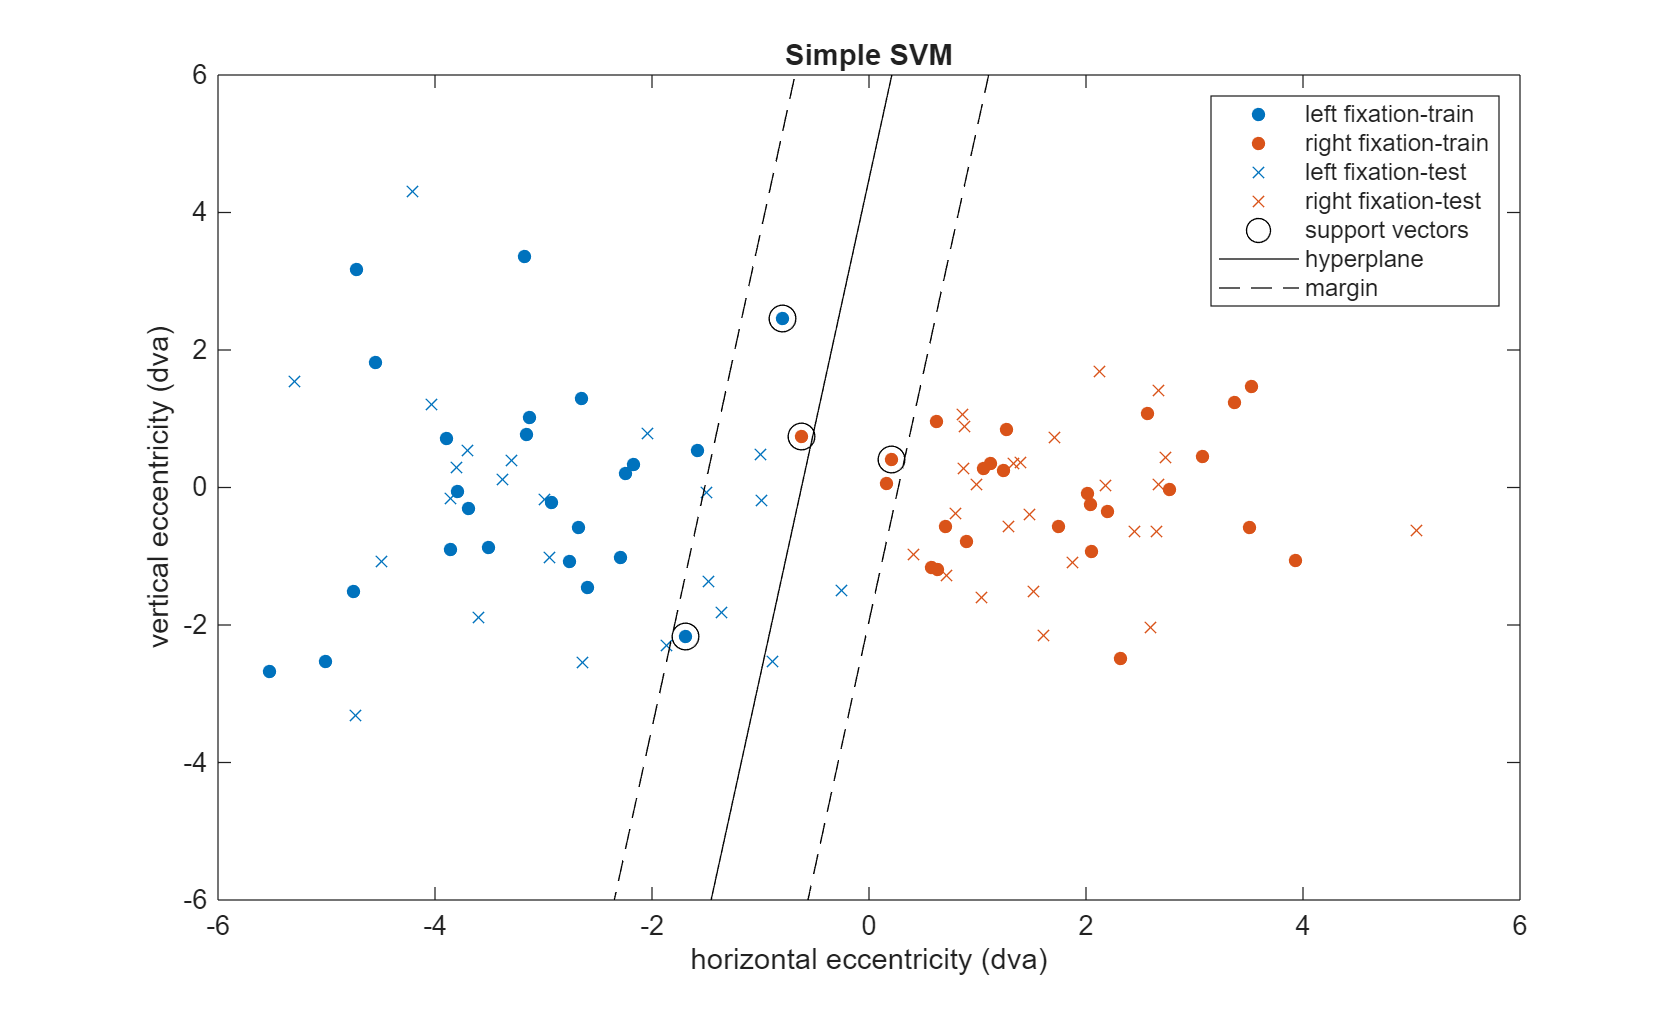

% plot the support vectors, separating hyperplane, and margin
sv = simpleSVM.SupportVectors;
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)

intercept = simpleSVM.Bias;
betas = simpleSVM.Beta;
xPred = linspace(-6,6);

% compute the margin
margin = 1/sqrt(sum(betas).^2);

% equation for a 1-dimensional separating hyperplane (i.e., a line)
y = @(x) (-intercept - betas(1).*xPred)/betas(2);

% plot hyperplane
plot(xPred,y(xPred),'k')

% add margin 
plot(xPred,y(xPred)-(margin*(betas(1)/betas(2))),'k--') 
plot(xPred,y(xPred)+(margin*(betas(1)/betas(2))),'k--') 
legend off

legend({'left fixation-train','right fixation-train',...
    'left fixation-test','right fixation-test',...
    'support vectors',...
    'hyperplane','margin'})
xlim([-6 6])
ylim([-6 6])

In the figure above, we can see that there are 4 support vectors, all of which fall within the soft-margin. When we  look at the test data, we see the two points are misclassified (the two blue x's to the right of the black line (the classification hyperplane)). Out of the 50 test-data points, this amounts to a misclassification rate of 4%. Since it is a relatively small sample, this is easy to calculate by hand. For larger data sets we can use the `loss `function to calculate this for us. 

%% calculate misclassification accuracy
errorRate = loss(simpleSVM,eyeData(testInds,1:2),eyeData.fixType(testInds));
disp(['out-of-sample misclassification is ', num2str(errorRate*100),'%']);

out-of-sample misclassification is 4%


### Example 2: 3 Features / 2 Classes

In the previous examples, we focused on classifying the data into fixations to the left vs. fixations to the right based only on the horizontal and vertical positions of the eyes. Now, let's classify the data into the same two classes, but we will add a third feature, the change in pupil diameter. Remember that the number of dimensions for the separating hyperplane is the number of features - 1. So, the only conceptual difference between this classification problem and the one in Example 1 is that the feature space is now 3-dimensional so the separating hyperplane is now a 2D plane instead of a line (1-dimensional). 

clear;clc
rng(10,'twister')
load ../data/svm3feature
classes = eyeData.fixType; % useful for indexing in the 3d plot commands later
svm3feat = fitcsvm(eyeData,'fixType','ClassNames',{'left','right'},...
    'PredictorNames',{'horizontalPos','verticalPos','pupilSize'});
sv = svm3feat.SupportVectors;
figure('Name','3-Feature SVM - binary classification')
clf

% gscatter does not exist for 3d plots. There are few different ways to
% emulate it, but I have found plot3 to be the most straight forward
plot3(eyeData.horizontalPos(classes == 'left'),eyeData.verticalPos(classes == 'left'),eyeData.pupilSize(classes == 'left'),'r.',...
    eyeData.horizontalPos(classes == 'right'),eyeData.verticalPos(classes == 'right'),eyeData.pupilSize(classes == 'right'),'b.',...
    'MarkerSize',20)

xlim([-6 6])
ylim([-6 6])
ylabel({'vertical eccentricity';'(dva)'})
xlabel({'horizontal eccentricity';'(dva)'})
zlabel({'\Delta pupil diameter';'(mm)'})
title('3-Feature SVM')
hold on

%% plot support vectors
plot3(sv(:,1),sv(:,2), sv(:,3),'ko','MarkerSize',10,'lineWidth',1);hold on

% calculate hyperplane
intercept = svm3feat.Bias;
betas = svm3feat.Beta;


The equation for the seperating hyperplane with a linear kernel is simply the equation of a plane: $\textrm{ax}+\textrm{by}+\textrm{cz}+d=0$. Using regression terminology: $\beta_1 x+\beta_2 y+\beta_3 z\;{+\;\beta }_0 =0$.  Solving for z, we get:  $z=\frac{-\beta_1 x-{\beta_2 y-\;\beta }_0 }{\beta_3 }\;$.

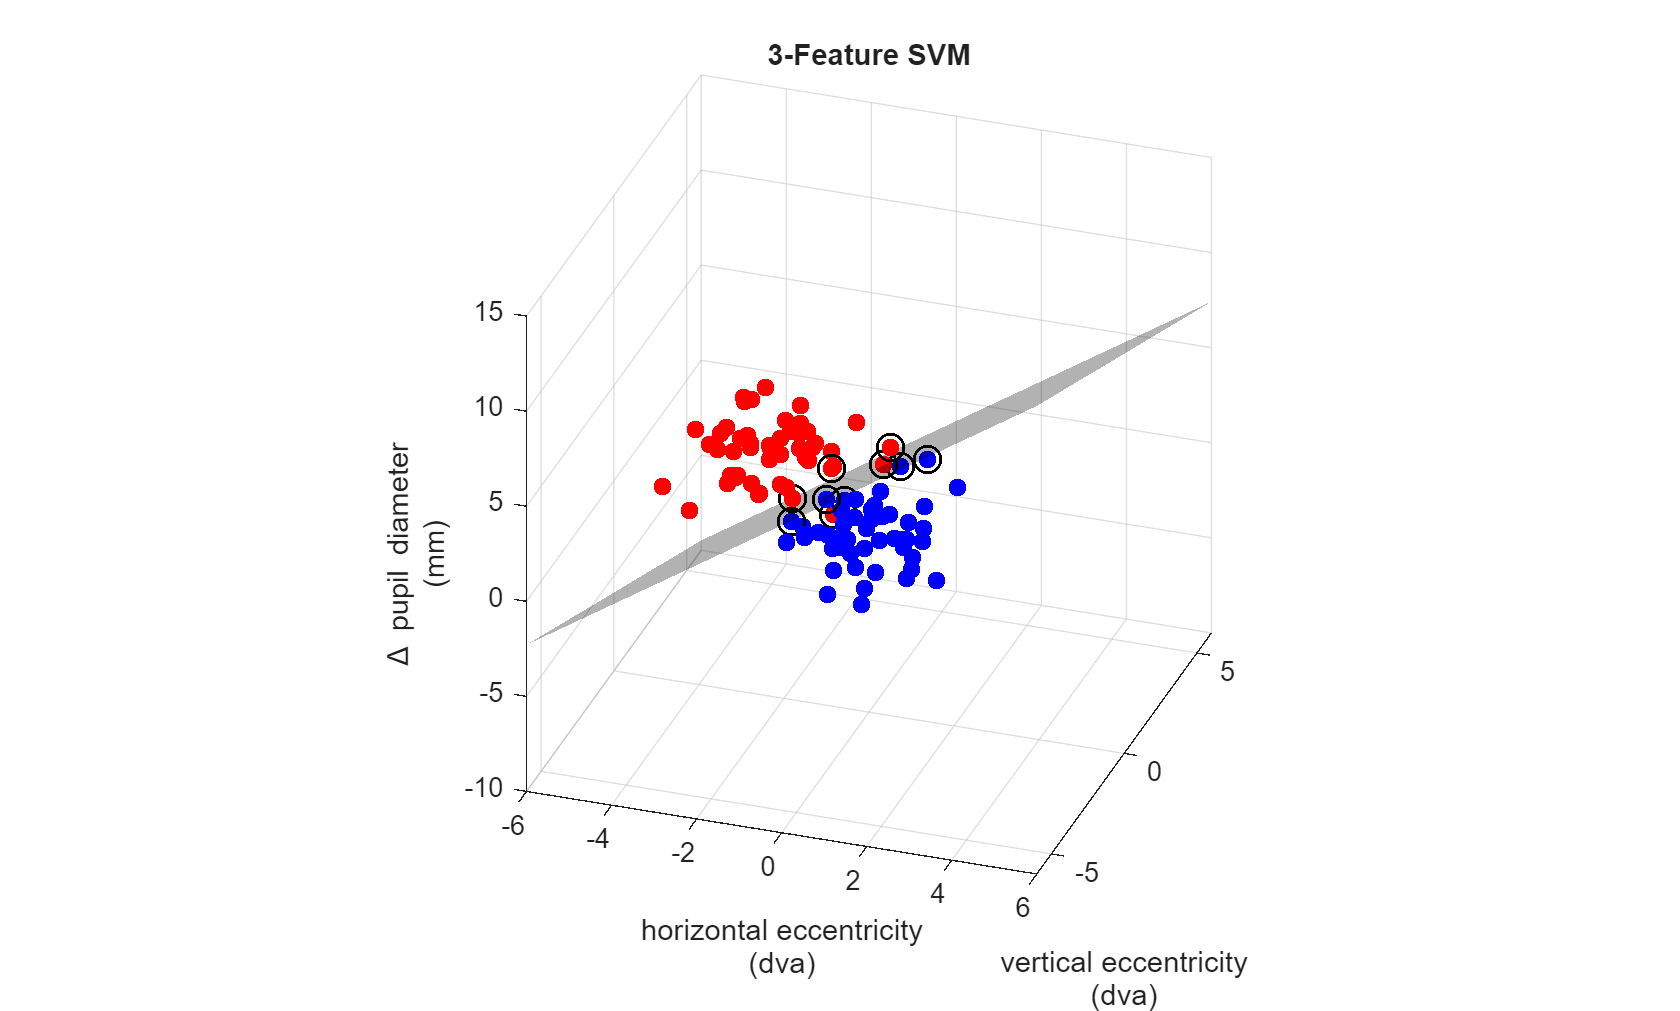

z = @(x,y)(-betas(1)*x-betas(2)*y-intercept)/betas(3);

% top left, top right, bottom right, bottom left
xx = [-6,6,6,-6,];
yy = [6,6,-6,-6];
zz = z(xx,yy);
% create a pacth to show the hyperplane
patch(xx,yy,zz,'k','EdgeColor','none','FaceAlpha',0.3)
grid on
legend off 
pbaspect([1 1 1])

% this is arbitrary, you can play with the code and see it (or press the
% circular arrow above the axis and rotate the view by mouse)
view([18.9 28.2])

Unlike in Example 1, where we held out half of the data and trained the classifier on the other half, for Examples 2 & 3 we are going to use 10-fold cross-validation which is the default using the `crossval` function. However, since it is messy to graphically show which data were used for each fold, the figures depicting the hyperplanes and support vectors for Examples 2 & 3 use SVMs trained on the entire data set. In reality, of course, you should always crossvalidate your classifiers! 

% cross validate the model with 10-fold CV
cv3feat = crossval(svm3feat);
classificationError = kfoldLoss(cv3feat);
disp(['out-of-sample misclassification is ', num2str(classificationError*100),'%']);

out-of-sample misclassification is 3%


### Example 3: Using SVMs with more than 2 Classes

At their core, SVMs are binary classifiers--they classify data into one of two classes based on whether it is on one side of a hyperplane or another. This is true even in a case with more than 2 classes. In these instances, SVMs work as part of an *error-correcting output codes (ECOC) model. *These models break down multiclass classification problems into a series of binary ones. The two most common ways of specifying ECOC models are called  *'One vs. All'  *and* 'One vs. One'*  models*. *In Matlab, this is accomplished by using the `fitcecoc` function. By default, `fitceoc` uses a one vs. one scheme. 

#### One vs. One (OVO)

For an OVO design, the algorithm creates N*(N-1)/2 SVM classifiers where N is the total number of classes. In other words, the ECOC creates one SVM for every *unique* pair of classes (left vs. right and right vs. left are the same thing). This is why it called one vs. one, it pits a single class against another single class. 

In the earlier examples, we classified eye positions as being either "left fixations" or "right fixations". Now we are going to add a third class, "central fixations". If you wanted to separate the eye data into these 3 types of fixations (left, center, right) using a OVO design, you would train the following 3 SVMs:

- Left vs. Center 

- Left vs. Right 

- Center vs. Right 

The syntax for ECOC models is nearly the same as binary svms. Each of the SVMs is stored within a cell that can be accessed through `ecocModel.BinaryLearners`. You can view which set of classes are within each SVM by looking at the coding matrix (`ecocModel.CodingMatrix`). The pair of classes for each model will have either have 1 or -1. A class not used in a given model will have a value of 0. Another special thing to note about the `fitcecoc `function is that it creates a series of "compact" SVM models. In other words, in order to save memory, the ecoc model does not save certain information for each of the svms. For instance, it does not supply the support vectors. However, you can feed `fitcecoc` a 'Learners' template which instructs the ecoc model to save this information. 

clear; clc
rng default
load ../data/multi-class-eyeData

tempECOC = templateSVM('SaveSupportVectors',true);
ecocModelOVO = fitcecoc(eyeData,'fixType','Learners',tempECOC,'ClassNames',{'left','center','right'},...
    'PredictorNames',{'horizontalPos','verticalPos'},'Coding','onevsone'); 


It is helpful to use the classNames option here because it allows you to specify the order of the classes. This way, you can more easily interpret the coding matrix. If you don't set the order, you can still see the order by accessing `ecocModel.ClassNames`. 

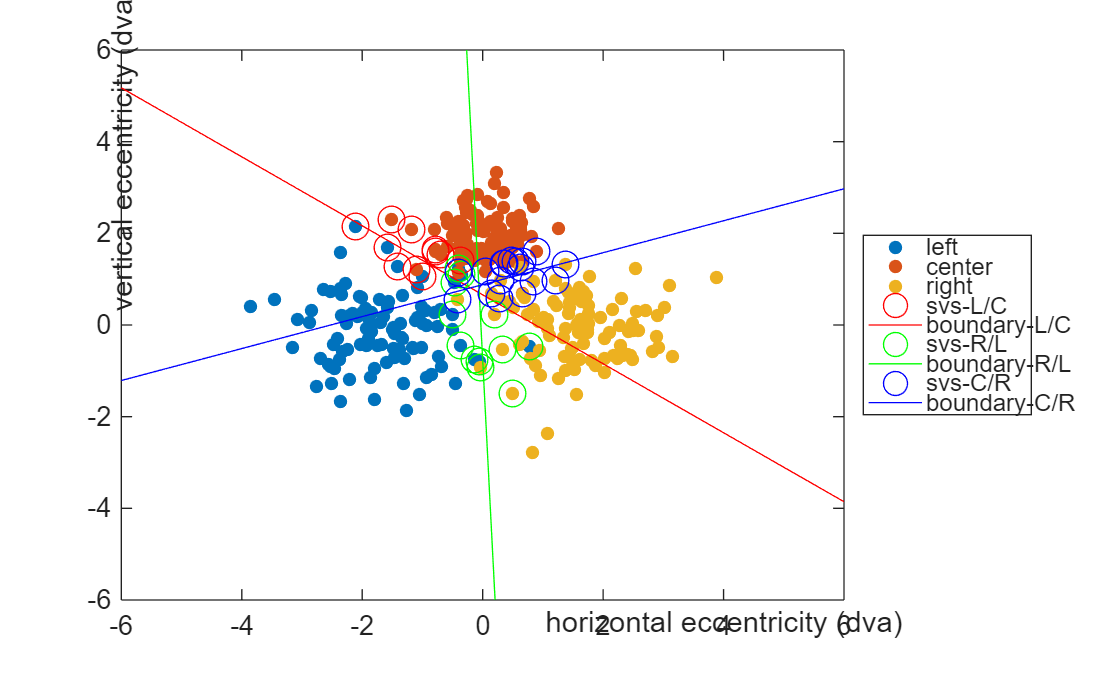


% plot the original data
figure('Name','Multiclass SVM - One vs. One')
clf
gscatter(eyeData.horizontalPos,eyeData.verticalPos,eyeData.fixType);
xlim([-6 6])
ylim([-6 6])
ylabel('vertical eccentricity (dva)')
xlabel('horizontal eccentricity (dva)')
title('One vs. One')
hold on

% add suppoprt vectors and hyperplanes
svsOVO = cellfun(@(x) x.SupportVectors,ecocModelOVO.BinaryLearners,'uni',0);
intercept = cellfun(@(x) x.Bias,ecocModelOVO.BinaryLearners);
betas = cellfun(@(x) x.Beta,ecocModelOVO.BinaryLearners,'uni',0);
xPred = linspace(-6,6);
colors = 'rgb'; % set the colors for the three hyperplanes
for i = 1:3
    
    % plot support vectors
    plot(svsOVO{i}(:,1),svsOVO{i}(:,2),[colors(i),'o'],'markerSize',10)
    
    % this is the same equation as in the 2-feature binary classification example with 
    % a modification made to allow for cell indexing
    y = @(x) (-intercept(i) - betas{i}(1).*xPred)/betas{i}(2);

    % plot hyperplane for each svm
    plot(xPred,y(xPred),colors(i))
end
legend({'left','center','right','svs-L/C','boundary-L/C', 'svs-R/L','boundary-R/L',...
    'svs-C/R','boundary-C/R'},'NumColumns',1,'Location','EastOutside')

#### One vs. All (OVA)

Using an OVA design (sometimes called OVR for one vs. rest), the algorithm generates 1 SVM for every class. So, if there are three classes, there are three SVMs. For each SVM, the hyperplane separates a single class from all of the other classes. 

Thus, if you wanted to separate the eye data into 3 types of fixations (left, center, right) using a OVA design, you would train ECOC model with the following 3 SVMs:

- Left vs. Not Left (i.e., center and right)

- Center vs. Not Center (i.e., left and right)

- Right vs. Not Right (i.e., center and left)

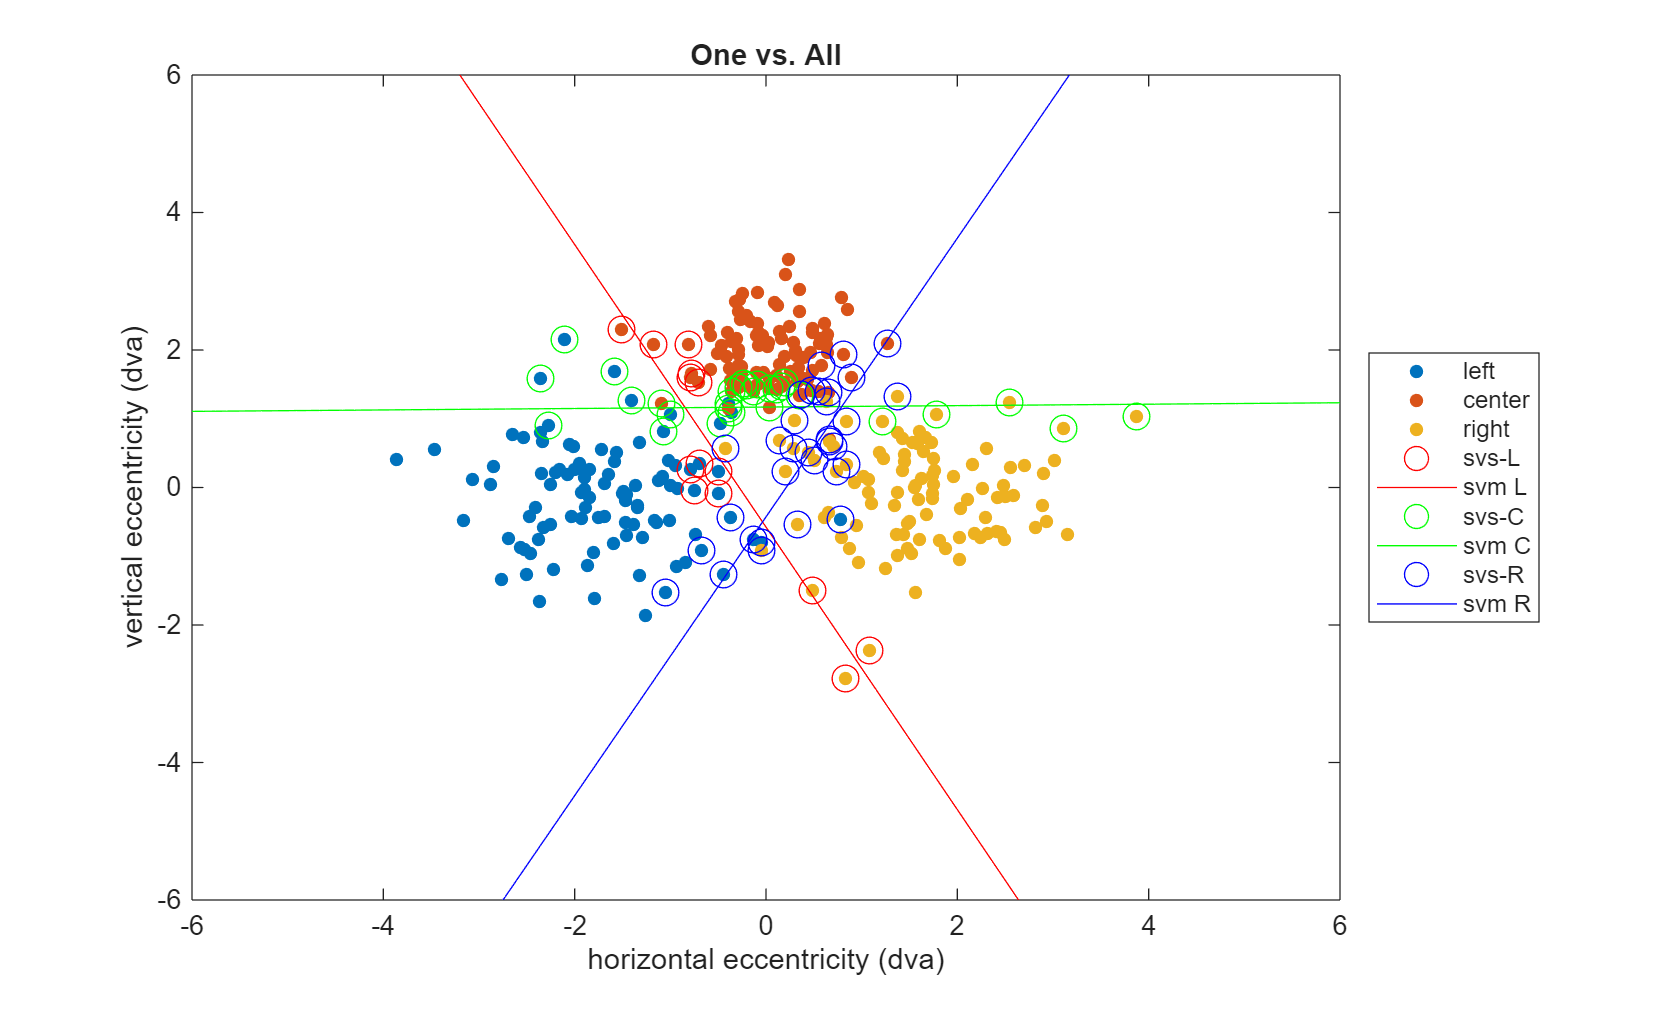

ecocModelOVA = fitcecoc(eyeData,'fixType','Learners',tempECOC,'ClassNames',{'left','center','right'},...
    'PredictorNames',{'horizontalPos','verticalPos'},'Coding','onevsall');

figure('Name','Multiclass SVM - One vs. All')
g = gscatter(eyeData.horizontalPos,eyeData.verticalPos,eyeData.fixType);hold on
legend off
xlim([-6 6])
ylim([-6 6])
ylabel('vertical eccentricity (dva)')
xlabel('horizontal eccentricity (dva)')
title('One vs. All')

% add suppoprt vectors and hyperplanes
svsOVA = cellfun(@(x) x.SupportVectors,ecocModelOVA.BinaryLearners,'uni',0);
intercept = cellfun(@(x) x.Bias,ecocModelOVA.BinaryLearners);
betas = cellfun(@(x) x.Beta,ecocModelOVA.BinaryLearners,'uni',0);
xPred = linspace(-6,6);
colors = 'rgb'; % set the colors for the three hyperplane

for i = 1:3
    plot(svsOVA{i}(:,1),svsOVA{i}(:,2),[colors(i),'o'],'markerSize',10)
    % this is the same equation as in the 2-feature binary classification example with 
    % a modification made to allow for cell indexing
    y = @(x) (-intercept(i) - betas{i}(1).*xPred)/betas{i}(2);

    % plot hyperplane for each svm
    plot(xPred,y(xPred),colors(i))
end

legend({'left','center','right','svs-L','svm L',...
    'svs-C','svm C','svs-R','svm R'},'Location','eastoutside')

% crossvalidate the OVO model using 10-fold cv
cvEcocOVO = crossval(ecocModelOVO);
classificationError = kfoldLoss(cvEcocOVO);
disp(['out-of-sample misclassification is ', num2str(classificationError*100),'%']);

out-of-sample misclassification is 3.3333%



% cross validate the OVA model
cvEcocOVA = crossval(ecocModelOVA);
classificationError = kfoldLoss(cvEcocOVA);
disp(['out-of-sample misclassification is ', num2str(classificationError*100),'%']);

out-of-sample misclassification is 4%


As you can see both models perform well, with the OVO model performing slightly better. To see where the two models are making their respective errors, we can use a confusion chart. 

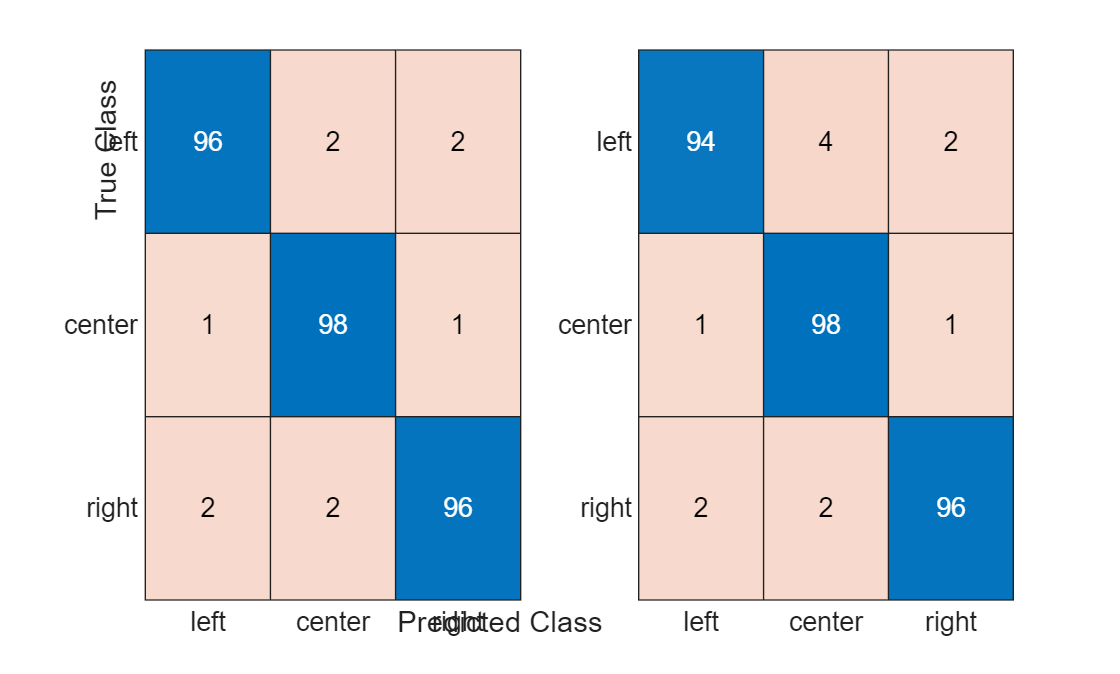

% create confusion charts to show the predictive accuracy breakdown for the
% two ecoc models
subplot(1,2,1)
ovoPred = kfoldPredict(cvEcocOVO);
ovoConCh = confusionchart(eyeData.fixType,categorical(ovoPred));
title 'one vs. one'

subplot(1,2,2)
ovaPred = kfoldPredict(cvEcocOVA);
ovaConCh = confusionchart(eyeData.fixType,categorical(ovaPred));
title 'one vs. all'

With only 3 classes, the number of SVMs in the OVA and OVO models are the same, so it makes sense that they make similar predictions. However, imagine if we had 4 classes. In this case OVA would use 4 SVMs and OVO would use 6. With 5 classes there are 10 SVMs in an OVO model. And so on... Of course the more SVMs you have, the better your classification accuracy. However, with a large numbers of classes using OVO becomes very computationally expensive. In these cases it may be more advisable to use an OVA model. 

## Resources

StatQuest SVM playlist: [https://www.youtube.com/playlist?list=PLzwVRKnDdXIfAOzylenX_4HIwT1fHWPp8](https://www.youtube.com/playlist?list=PLzwVRKnDdXIfAOzylenX_4HIwT1fHWPp8)

ISLR SVM playlist: [https://www.youtube.com/playlist?list=PLAOUn-KLSAVOf4Uk-WbLGPUDFjMSyytkw](https://www.youtube.com/playlist?list=PLAOUn-KLSAVOf4Uk-WbLGPUDFjMSyytkw)